
[1/7] Processing: Raji_FA 10% _ 001_DIC_MIP_mask.jpg


  detected clusters: 1


    cluster 1: no split, original kept


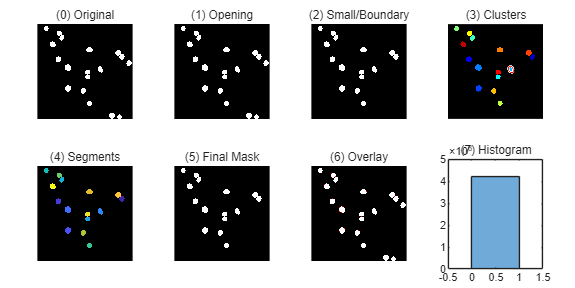


[2/7] Processing: Raji_FA 10% _ 002_DIC_MIP_mask.jpg


  detected clusters: 1


    cluster 1: watershed split used (ridgeWidth=4)


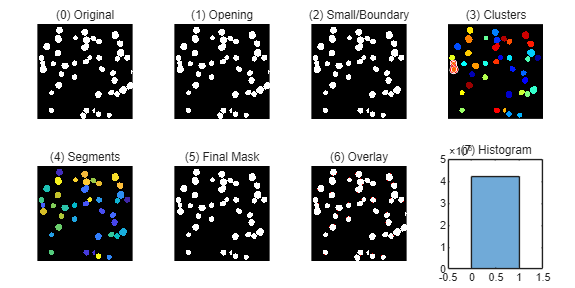


[3/7] Processing: Raji_FA 10% _ 003_DIC_MIP_mask.jpg


  detected clusters: 0


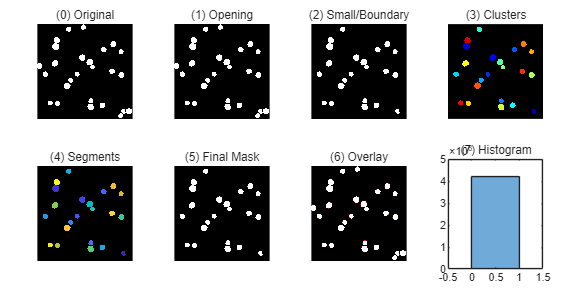


[4/7] Processing: Raji_FA 10% _ 004_DIC_MIP_mask.jpg


  detected clusters: 5


    cluster 1: watershed split used (ridgeWidth=4)
    cluster 2: watershed split used (ridgeWidth=4)
    cluster 3: watershed split used (ridgeWidth=4)
    cluster 4: watershed split used (ridgeWidth=4)
    cluster 5: watershed split used (ridgeWidth=4)


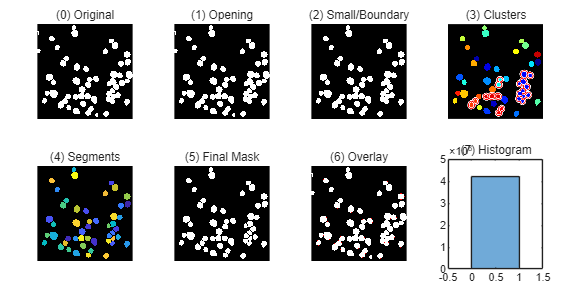


[5/7] Processing: Raji_FA 10% _ 005_DIC_MIP_mask.jpg


  detected clusters: 4


    cluster 1: watershed split used (ridgeWidth=4)
    cluster 2: watershed split used (ridgeWidth=4)
    cluster 3: watershed split used (ridgeWidth=4)
    cluster 4: watershed split used (ridgeWidth=4)


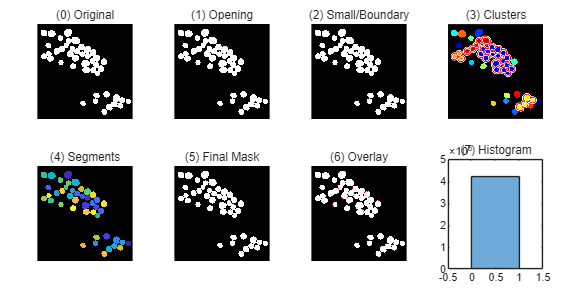


[6/7] Processing: Raji_FA 10% _ 006_DIC_MIP_mask.jpg


  detected clusters: 2


    cluster 1: watershed split used (ridgeWidth=4)
    cluster 2: watershed split used (ridgeWidth=4)


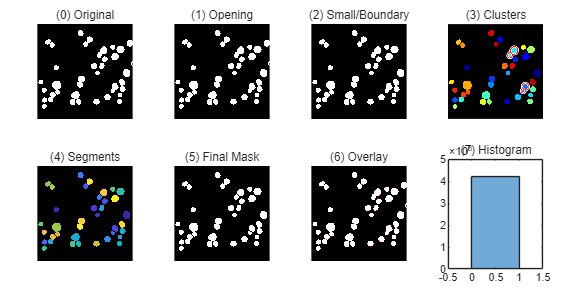


[7/7] Processing: Raji_FA 10% _ 007_DIC_MIP_mask.jpg


  detected clusters: 0


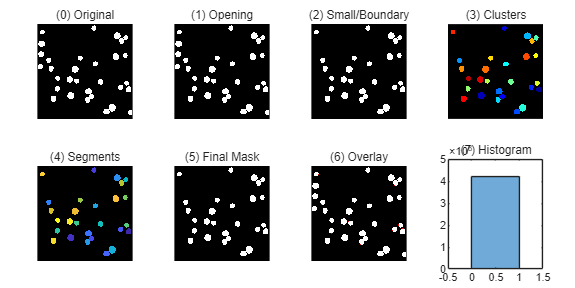

%% Touching-Cell Splitting for Binary Mask
% 1) Opening
% 2) Small & Boundary Removal
% 3) Cluster Detection
% 4) Split Cluster
%    - First: thick-ridge marker-controlled watershed
%    - Second: concavity-based cut
% 5) Hole Fill
% 6) Display (2x4)
% 7) Save Result

clear; clc; close all;

%% =========================
% Parameters
% ==========================
inputDir    = 'J:\HG\260314_mRNA calibration _GMA+FA\CD79B\03.Mask';
outputDir   = 'J:\HG\260314_mRNA calibration _GMA+FA\CD79B\03.Mask_sperate and edge';
filePattern = '*.jpg';   % 필요하면 '*.png' 또는 '*.tif'로 변경

% ---- 기본 필터링 ----
minArea       = 5000;     % 최소 cell area
margin        = 20;       % boundary margin
solidityT     = 0.90;     % cluster 판별용 solidity threshold
eccentricityT = 0.70;     % cluster 판별용 eccentricity threshold
openingRadius = 2;        % opening radius

% ---- watershed splitting ----
distSigma     = 1.2;                % distance map smoothing
peakHList     = [1.2 0.9 0.6];      % 큰 값 -> 보수적, 작은 값 -> 더 잘 쪼갬
markerMinArea = 5;                  % 작은 marker 제거
ridgeWidth    = 4;                  % watershed 경계 두께 (중요)

% ---- concavity splitting ----
cutWidth      = 4;                  % concavity cut line 두께 (중요)
defectMinArea = 20;                 % 너무 작은 concavity 제거
splitMinKeep  = max(round(0.20*minArea), 20);   % split 후 최소 유지 면적

% ---- 옵션 ----
showFigure    = true;
saveResult    = true;
debugPrint    = true;   % 각 cluster가 어떤 방식으로 split 되었는지 출력
debugCutPlot  = false;  % concavity cut line 디버그 표시

if ~exist(outputDir, 'dir')
    mkdir(outputDir);
end

files = dir(fullfile(inputDir, filePattern));
if isempty(files)
    error('No files found in: %s', fullfile(inputDir, filePattern));
end

%% =========================
% Main Loop
% ==========================
for k = 1:numel(files)

    fname = files(k).name;
    fpath = fullfile(inputDir, fname);

    fprintf('\n[%d/%d] Processing: %s\n', k, numel(files), fname);

    I = imread(fpath);
    bw0 = makeLogicalMask(I);       % (0) Original binary mask
    [H, W] = size(bw0);

    % ---------------------------------
    % (1) Opening
    % ---------------------------------
    bw1 = imopen(bw0, strel('disk', openingRadius));

    % ---------------------------------
    % (2) Small & Boundary Removal
    % ---------------------------------
    bw2 = removeSmallAndBoundaryObjects(bw1, minArea, margin);

    % ---------------------------------
    % (3) Cluster Detection
    % ---------------------------------
    [bwClust, L2] = detectClusters(bw2, minArea, solidityT, eccentricityT);

    % ---------------------------------
    % (4) Split Cluster Objects
    % ---------------------------------
    finalMask = bw2 & ~bwClust;   % non-cluster는 그대로 보존
    CCclust   = bwconncomp(bwClust, 8);

    if debugPrint
        fprintf('  detected clusters: %d\n', CCclust.NumObjects);
    end

    for i = 1:CCclust.NumObjects
        maskI = false(H, W);
        maskI(CCclust.PixelIdxList{i}) = true;

        % ---- 1차: thick-ridge marker-controlled watershed ----
        [splitMask1, success1] = tryMarkerWatershedSplit( ...
            maskI, peakHList, distSigma, markerMinArea, splitMinKeep, ridgeWidth);

        if success1
            finalMask = finalMask | splitMask1;
            if debugPrint
                fprintf('    cluster %d: watershed split used (ridgeWidth=%d)\n', i, ridgeWidth);
            end
            continue;
        end

        % ---- 2차: concavity-based cut ----
        [splitMask2, success2] = splitByConcavity( ...
            maskI, cutWidth, defectMinArea, splitMinKeep, debugCutPlot);

        if success2
            finalMask = finalMask | splitMask2;
            if debugPrint
                fprintf('    cluster %d: concavity split used (cutWidth=%d)\n', i, cutWidth);
            end
        else
            finalMask = finalMask | maskI;
            if debugPrint
                fprintf('    cluster %d: no split, original kept\n', i);
            end
        end
    end

    % ---------------------------------
    % (5) Hole Fill per Component
    % ---------------------------------
    finalMask = fillEachComponent(finalMask);
    finalMask = smoothEachComponent(finalMask, 10.0);
    % ---------------------------------
    % (6) Display
    % ---------------------------------
    if showFigure
        figure('Name', fname, 'Units', 'normalized', 'Position', [0.05 0.08 0.90 0.80]);
        tiledlayout(2,4, 'TileSpacing', 'compact', 'Padding', 'compact');

        nexttile;
        imshow(bw0);
        title('(0) Original');

        nexttile;
        imshow(bw1);
        title('(1) Opening');

        nexttile;
        imshow(bw2);
        title('(2) Small/Boundary');

        nexttile;
        imshow(label2rgb(L2, 'jet', 'k', 'shuffle'));
        hold on;
        visboundaries(bwClust, 'Color', 'r', 'LineWidth', 0.8);
        title('(3) Clusters');
        hold off;

        nexttile;
        Lfin = bwlabel(finalMask, 8);
        imshow(label2rgb(Lfin, 'parula', 'k', 'shuffle'));
        title('(4) Segments');

        nexttile;
        imshow(finalMask);
        title('(5) Final Mask');

        nexttile;
        ov = imoverlay(bw0, bwperim(finalMask), [1 0 0]);
        imshow(ov);
        title('(6) Overlay');

        nexttile;
        histogram(double(finalMask(:)), [0 1]);
        xlim([-0.5 1.5]);
        title('(7) Histogram');

        drawnow;
    end

    % ---------------------------------
    % (7) Save
    % ---------------------------------
    if saveResult
        imwrite(uint8(finalMask)*255, fullfile(outputDir, fname));
    end
end


fprintf('\nDone: split masks written to\n%s\n', outputDir);


Done: split masks written to
J:\HG\260314_mRNA calibration _GMA+FA\CD79B\03.Mask_sperate and edge



%% ========================================================================
% Local Functions
% ========================================================================

function bw = makeLogicalMask(I)
    % RGB / grayscale 모두 처리
    if ndims(I) == 3
        bw = any(I > 0, 3);
    else
        bw = I > 0;
    end
    bw = logical(bw);
end

function bwOut = removeSmallAndBoundaryObjects(bwIn, minArea, margin)
    [H, W] = size(bwIn);
    L = bwlabel(bwIn, 8);
    stats = regionprops(L, 'Area', 'BoundingBox', 'PixelIdxList');

    bwOut = false(H, W);

    for i = 1:numel(stats)
        A  = stats(i).Area;
        bb = stats(i).BoundingBox;   % [x y w h]

        x1 = bb(1);
        y1 = bb(2);
        x2 = x1 + bb(3) - 1;
        y2 = y1 + bb(4) - 1;

        inside = (x1 > margin) && (y1 > margin) && ...
                 (x2 <= W - margin) && (y2 <= H - margin);

        if A >= minArea && inside
            bwOut(stats(i).PixelIdxList) = true;
        end
    end
end

function [bwClust, L] = detectClusters(bwIn, minArea, solidityT, eccentricityT)
    [H, W] = size(bwIn);

    L = bwlabel(bwIn, 8);
    stats = regionprops(L, 'Area', 'Solidity', 'Eccentricity', 'PixelIdxList');

    bwClust = false(H, W);

    for i = 1:numel(stats)
        A   = stats(i).Area;
        sol = stats(i).Solidity;
        ecc = stats(i).Eccentricity;

        % 크기도 크고, 모양도 비정상적인 경우 cluster 후보로 판단
        if A > 2*minArea && (sol < solidityT || ecc > eccentricityT)
            bwClust(stats(i).PixelIdxList) = true;
        end
    end
end

function [splitMask, success] = tryMarkerWatershedSplit(maskI, peakHList, distSigma, markerMinArea, splitMinKeep, ridgeWidth)

    splitMask = maskI;
    success   = false;

    % distance transform
    D  = bwdist(~maskI);
    Ds = imgaussfilt(D, distSigma);

    for h = peakHList

        % 내부 peak(marker) 찾기
        marks = imextendedmax(Ds, h);
        marks = marks & maskI;
        marks = bwareaopen(marks, markerMinArea);
        marks = imclose(marks, strel('disk', 1));

        CCm = bwconncomp(marks, 8);
        if CCm.NumObjects < 2
            continue;
        end

        % marker-controlled watershed
        Lw = watershed(imimposemin(-Ds, marks | ~maskI));
        Lw(~maskI) = 0;

        % watershed ridge를 두껍게
        ridge = (Lw == 0);
        ridge = ridge & maskI;
        ridge = imdilate(ridge, strel('disk', ridgeWidth));
        ridge = ridge & maskI;

        % ridge 제거 후 split
        tmp = maskI & ~ridge;
        tmp = bwareaopen(tmp, splitMinKeep);
        tmp = fillEachComponent(tmp);

        CCs = bwconncomp(tmp, 8);
        if CCs.NumObjects >= 2
            splitMask = tmp;
            success   = true;
            return;
        end
    end
end

function [outMask, success] = splitByConcavity(maskI, cutWidth, defectMinArea, splitMinKeep, debugCutPlot)

    outMask = maskI;
    success = false;

    % convex hull과 원본 차이 = concavity defect
    hullMask = bwconvhull(maskI);
    defect   = hullMask & ~maskI;
    defect   = bwareaopen(defect, defectMinArea);

    CCd = bwconncomp(defect, 8);
    if CCd.NumObjects < 2
        return;
    end

    stats = regionprops(CCd, 'Area', 'Centroid');

    % defect가 여러 개면 가장 큰 2개 사용
    allAreas   = [stats.Area];
    [~, order] = sort(allAreas, 'descend');

    idx1 = order(1);
    idx2 = order(2);

    c1 = stats(idx1).Centroid;   % [x y]
    c2 = stats(idx2).Centroid;   % [x y]

    % 두 concavity 중심을 연결하는 line 생성
    cutLine = makeLineMask(size(maskI), c1, c2);

    % line 두껍게
    cutLine = imdilate(cutLine, strel('disk', cutWidth));
    cutLine = cutLine & maskI;

    if debugCutPlot
        figure;
        tiledlayout(1,3, 'TileSpacing', 'compact', 'Padding', 'compact');

        nexttile;
        imshow(maskI);
        title('maskI');

        nexttile;
        imshow(defect);
        title('concavity defect');

        nexttile;
        imshow(maskI); hold on;
        visboundaries(cutLine, 'Color', 'r', 'LineWidth', 1);
        title(sprintf('cut line (cutWidth=%d)', cutWidth));
        hold off;
    end

    % 실제 마스크에서 cut
    tmp = maskI & ~cutLine;
    tmp = bwareaopen(tmp, splitMinKeep);
    tmp = fillEachComponent(tmp);

    CCs = bwconncomp(tmp, 8);
    if CCs.NumObjects >= 2
        outMask = tmp;
        success = true;
    end
end

function lineMask = makeLineMask(imSize, p1, p2)
    % p1, p2 = [x y]
    n = max(ceil(norm(p1 - p2) * 4), 10);

    xs = round(linspace(p1(1), p2(1), n));
    ys = round(linspace(p1(2), p2(2), n));

    valid = xs >= 1 & xs <= imSize(2) & ys >= 1 & ys <= imSize(1);

    xs = xs(valid);
    ys = ys(valid);

    lineMask = false(imSize);
    idx = sub2ind(imSize, ys, xs);
    lineMask(idx) = true;
end

function bwOut = fillEachComponent(bwIn)
    L = bwlabel(bwIn, 8);
    bwOut = false(size(bwIn));

    nObj = max(L(:));
    for i = 1:nObj
        comp = (L == i);
        compFill = imfill(comp, 'holes');
        bwOut = bwOut | compFill;
    end
end

function bwOut = smoothEachComponent(bwIn, sigma)
    L = bwlabel(bwIn, 8);
    bwOut = false(size(bwIn));

    nObj = max(L(:));
    for i = 1:nObj
        comp = (L == i);

        % signed distance map
        phi = bwdist(~comp) - bwdist(comp);

        % smooth
        phiS = imgaussfilt(phi, sigma);

        % threshold back to binary
        compS = phiS > 0;

        % hole fill
        compS = imfill(compS, 'holes');

        bwOut = bwOut | compS;
    end
end